第一问

**可以考虑Survival Analysis，也可以用t-test**

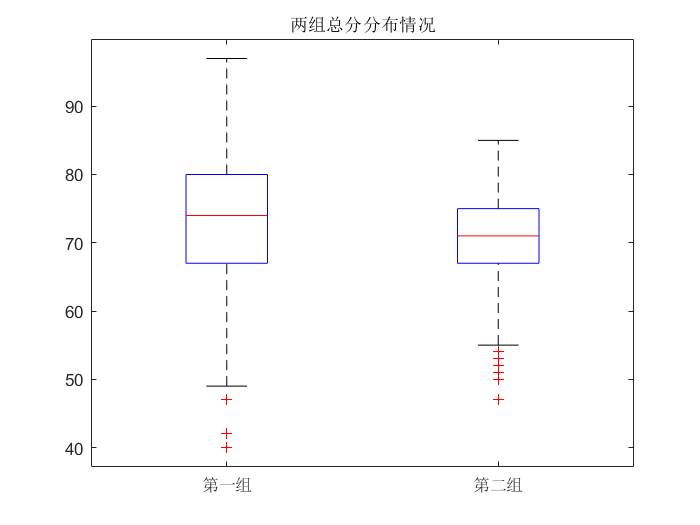

defeng=[defeng1(:),defeng2(:)];
figure
boxplot(defeng,'Labels',{'第一组','第二组'})
title 两组总分分布情况

[h,p,ci,stats] = ttest(defeng1(:),defeng2(:))%显著性差异

h = 1

p = 3.8940e-04

ci =     1.1483
    3.9332


stats = 包含以下字段的 struct :
    tstat: 3.5925
       df: 269
       sd: 11.6212


disp(['没有显著差异概率为',num2str(p)])

没有显著差异概率为0.0003894


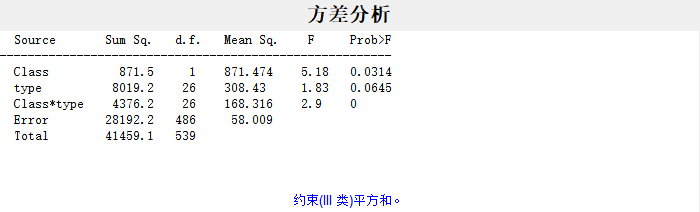

h0 =     0.0314
    0.0645
    0.0000


p0 = 6×15 cell 数组
    {'Source'    }    {'Sum Sq.'   }    {'d.f.'}    {'Singular?'}    {'Mean Sq.'}    {'F'       }    {'Prob>F'    }    {'Type'    }    {'Expected MS'                           }    {'MS denom'}    {'d.f. denom'}    {'Denom. defn.'  }    {'Var. est.'}    {'Var. lower bnd'}    {'Var. upper bnd'}
    {'Class'     }    {[  871.4741]}    {[   1]}    {[        0]}    {[871.4741]}    {[  5.1776]}    {[    0.0314]}    {'random'  }    {'270*V(Class)+10*V(Class*type)+V(Error)'}    {[168.3164]}    {[        26]}    {'MS(Class*type)'}    {[   2.6043]}    {[             0]}    {[    3.2862e+03]}
    {'type'      }    {[8.0192e+03]}    {[  26]}    {[        0]}    {[308.4301]}    {[  1.8324]}    {[    0.0645]}    {'fixed'   }    {'20*Q(type)+10*V(Class*type)+V(Error)'  }    {[168.3164]}    {[        26]}    {'MS(Class*type)'}    {0×0 double }    {0×0 double      }    {0×0 double      }
    {'Class*type'}    {[4.3762e+03]}    {[  26]}    {[        0]}    {[168.3164]}    {[  2.9016]}

stats0 = 包含以下字段的 struct :
         source: 'anovan'
          resid: [540×1 double]
         coeffs: [84×1 double]
            Rtr: [54×54 double]
       rowbasis: [54×84 double]
            dfe: 486
            mse: 58.0086
    nullproject: [84×54 double]
          terms: [3×2 double]
        nlevels: [2×1 double]
     continuous: [0 0]
         vmeans: [2×1 double]
       termcols: [4×1 double]
     coeffnames: {84×1 cell}
           vars: [84×2 double]
       varnames: {2×1 cell}
       grpnames: {2×1 cell}
        vnested: []
            ems: [4×4 double]
          denom: [3×3 double]
        dfdenom: [3×1 double]
        msdenom: [3×1 double]
         varest: [3×1 double]
          varci: [3×2 double]
       txtdenom: {3×1 cell}
         txtems: {4×1 cell}
        rtnames: {3×1 cell}





varnames = {'Class';'type'};%补一个葡萄酒种类问题
y=[defeng1;defeng2];
y=y(:);
Group=repmat([ones(27,1);2*ones(27,1)],10,1);
Class=[ones(54,1);2*ones(54,1);3*ones(54,1);4*ones(54,1);5*ones(54,1);6*ones(54,1);7*ones(54,1);8*ones(54,1);9*ones(54,1);10*ones(54,1)];
type1=repmat(type(:,1),1,10);
type1=type1(:);
type2=repmat(type(:,2),1,10);
type2=type2(:);
alltype=[type1;type2];
[h0,p0,stats0]=anovan(y,{Group,alltype},"varnames",varnames,'random',1,'model',"interaction")%多元方差分析，剔除掉组别和葡萄酒类别影响

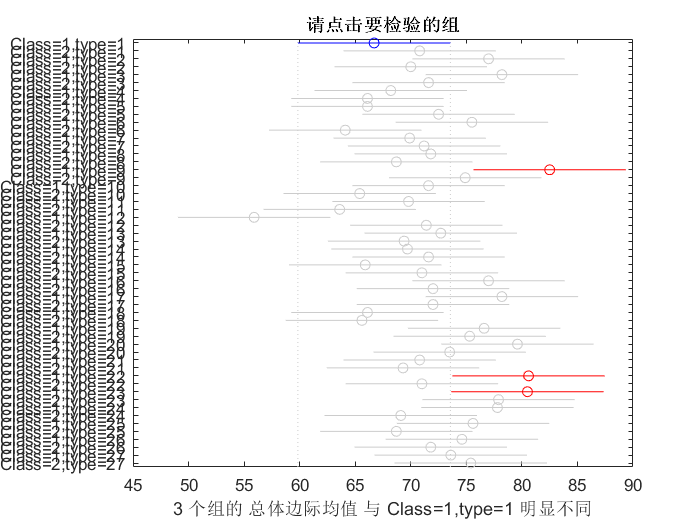

[results,~,~,gnames] = multcompare(stats0,'Dimension',[1,2]);

第二问

考虑利用GA，然后用交叉熵作为损失函数衡量标准

一次指标聚类处理$y=f(X,W;K)$

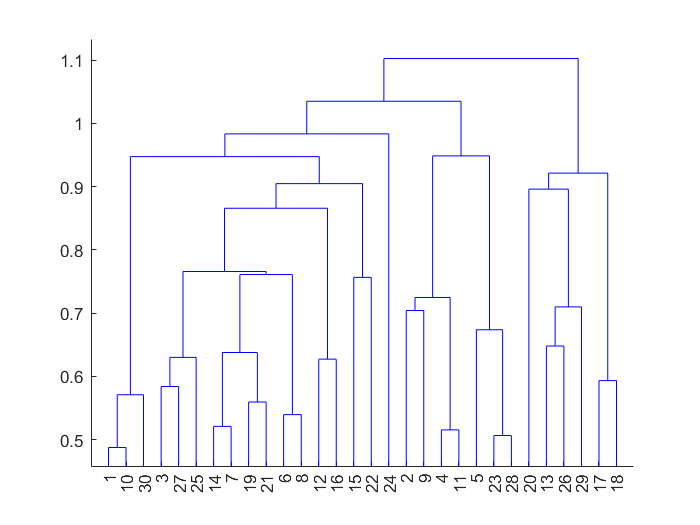

Data0=[Dataliangjiuhong,Datahongjiu];
Data0=zscore(Data0);
r=corrcoef(Data0);
d=pdist(Data0','correlation');
z=linkage(d,"average");
h=dendrogram(z);

不一定要用pca，可以用

t-SNE，NCA，多维标度法,ICA

Data=[Dataliangjiuhong,Datahongjiu];
    boxplot(Data,'Notch',"on",'Orientation','horizontal')
    title('10个指标的数据分布情况')
    C=corr(Data,Data)%检查成对相关性

C =     1.0000    0.2807    0.2118    0.3299   -0.0521    0.9778   -0.0319   -0.0003    0.1705    0.0340    0.1427   -0.0898    0.0182   -0.0970   -0.0377    0.2479    0.0412   -0.0178    0.0235   -0.1208    0.0807    0.3642   -0.0722    0.0829   -0.1181   -0.1528    0.1051    0.2591    0.1994    0.1307    0.0510   -0.0291    0.0557    0.0542   -0.0067    0.4654    0.3086    0.4628   -0.0599    0.5705    0.5803    0.4358    0.4403    0.4143    0.5534    0.2360    0.2041    0.0601    0.6010   -0.3831
    0.2807    1.0000    0.3109    0.3924    0.5338    0.1674    0.5313    0.5107    0.3256    0.2753    0.2034    0.2772    0.3393    0.3567    0.3970    0.1808    0.0750    0.0810   -0.0864    0.1211    0.2466   -0.1086    0.3128   -0.0233   -0.2782    0.1351    0.2804    0.4235    0.4345    0.3597    0.3095    0.0242    0.2854   -0.0735    0.4787    0.2940    0.2749    0.2879   -0.0849    0.3533    0.1133    0.0334   -0.0432    0.0886    0.1959    0.0832    0.0253    0.1637    0.0950   -0

    w=1./var(Data);
    [wcoeff,score,latent,tsquared,explained]=pca(Data,'Centered',true)%主成分分析开始

wcoeff =     0.7083    0.0454   -0.6227    0.0193    0.0714   -0.0759   -0.0844   -0.0003   -0.0006    0.0035   -0.0673   -0.0193    0.0187    0.0345    0.0172    0.0346    0.0196   -0.0750   -0.0187    0.0452    0.0330   -0.0706    0.0320   -0.0403   -0.0076    0.0034
    0.0021    0.0120   -0.0401    0.0048   -0.0177   -0.0336   -0.1013    0.1379    0.0163    0.1569    0.0136   -0.0960    0.2922    0.0824   -0.1888    0.5200    0.2509   -0.2025    0.1771   -0.1464   -0.1837    0.0289   -0.0523    0.1436    0.0746   -0.0344
    0.0056    0.1335   -0.1551    0.0765   -0.1286   -0.2384    0.4042   -0.1611   -0.0149   -0.3612    0.2497    0.3837   -0.3163    0.1747   -0.0270   -0.0179    0.1017   -0.1181    0.0654   -0.1420   -0.0232   -0.0470    0.1037    0.0784   -0.0974    0.0159
    0.0067   -0.0282   -0.1525   -0.0660    0.0034   -0.2798   -0.3291   -0.1849    0.2165   -0.2719   -0.2032   -0.1062   -0.0402   -0.0216    0.0056    0.0108   -0.2888    0.3859    0.0028   -0.2055   -0.05

score = 	1.0e+03 *

   -0.7668    1.1016   -0.2435    0.1829   -0.1526    0.0044    0.0613   -0.0564   -0.0086    0.0227    0.0565   -0.0178    0.0118   -0.0153   -0.0080    0.0040    0.0178   -0.0027   -0.0017    0.0055    0.0065    0.0029   -0.0047    0.0004   -0.0007   -0.0014
   -0.0990    0.4869    0.3107   -0.0826   -0.0568    0.1342   -0.0048   -0.0605    0.0079   -0.0235   -0.0339   -0.0158   -0.0007   -0.0014   -0.0092    0.0138   -0.0065    0.0111   -0.0030   -0.0180   -0.0117    0.0017    0.0014    0.0044    0.0020   -0.0033
    8.5201    0.1216    0.0583    0.0693    0.0545   -0.0280   -0.0288    0.0303    0.0285   -0.0012    0.0297    0.0224   -0.0137    0.0279   -0.0186    0.0105    0.0062   -0.0021    0.0006   -0.0011    0.0007    0.0054    0.0010   -0.0019   -0.0002   -0.0026
   -0.3443   -0.2611   -0.0478   -0.0681   -0.1941   -0.0261   -0.0224    0.0276    0.0347    0.0017   -0.0025    0.0214    0.0123   -0.0238   -0.0490   -0.0244   -0.0029    0.0081    0.0030    0.0

latent = 	1.0e+06 *

    4.8322
    0.1639
    0.0679
    0.0275
    0.0113
    0.0064
    0.0031
    0.0017
    0.0017
    0.0015


tsquared =    25.0370
   25.0370
   25.0370
   25.0370
   25.0370
   25.0370
   25.0370
   25.0370
   25.0370
   25.0370


explained =    94.3608
    3.2006
    1.3251
    0.5370
    0.2213
    0.1250
    0.0603
    0.0334
    0.0325
    0.0288


    c3=wcoeff(:,1:end)%成分系数

c3 =     0.7083    0.0454   -0.6227    0.0193    0.0714   -0.0759   -0.0844   -0.0003   -0.0006    0.0035   -0.0673   -0.0193    0.0187    0.0345    0.0172    0.0346    0.0196   -0.0750   -0.0187    0.0452    0.0330   -0.0706    0.0320   -0.0403   -0.0076    0.0034
    0.0021    0.0120   -0.0401    0.0048   -0.0177   -0.0336   -0.1013    0.1379    0.0163    0.1569    0.0136   -0.0960    0.2922    0.0824   -0.1888    0.5200    0.2509   -0.2025    0.1771   -0.1464   -0.1837    0.0289   -0.0523    0.1436    0.0746   -0.0344
    0.0056    0.1335   -0.1551    0.0765   -0.1286   -0.2384    0.4042   -0.1611   -0.0149   -0.3612    0.2497    0.3837   -0.3163    0.1747   -0.0270   -0.0179    0.1017   -0.1181    0.0654   -0.1420   -0.0232   -0.0470    0.1037    0.0784   -0.0974    0.0159
    0.0067   -0.0282   -0.1525   -0.0660    0.0034   -0.2798   -0.3291   -0.1849    0.2165   -0.2719   -0.2032   -0.1062   -0.0402   -0.0216    0.0056    0.0108   -0.2888    0.3859    0.0028   -0.2055   -0.0553  

    coefforth=diag(std(Data))\wcoeff%变换矩阵

coefforth =     0.0005    0.0000   -0.0004    0.0000    0.0000   -0.0000   -0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.0001    0.0006   -0.0019    0.0002   -0.0009   -0.0016   -0.0049    0.0067    0.0008    0.0076    0.0007   -0.0046    0.0141    0.0040   -0.0091    0.0251    0.0121   -0.0098    0.0086   -0.0071   -0.0089    0.0014   -0.0025    0.0069    0.0036   -0.0017
    0.0001    0.0017   -0.0019    0.0010   -0.0016   -0.0030    0.0050   -0.0020   -0.0002   -0.0045    0.0031    0.0048   -0.0040    0.0022   -0.0003   -0.0002    0.0013   -0.0015    0.0008   -0.0018   -0.0003   -0.0006    0.0013    0.0010   -0.0012    0.0002
    0.0001   -0.0005   -0.0027   -0.0012    0.0001   -0.0049   -0.0058   -0.0033    0.0038   -0.0048   -0.0036   -0.0019   -0.0007   -0.0004    0.0001    0.0002   -0.0051    0.0068    0.0000   -0.0036   -0

    I=coefforth'*coefforth%检查系数

I =     0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0001    0.0000   -0.0000    0.0000    0.0001
    0.0000    0.0001    0.0000    0.0000   -0.0000    0.0001   -0.0001    0.0000    0.0001    0.0000    0.0000   -0.0000    0.0001    0.0001    0.0001    0.0001   -0.0001   -0.0001   -0.0001   -0.0000   -0.0001   -0.0001    0.0001   -0.0000   -0.0000    0.0004
    0.0000    0.0000    0.0001    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0001   -0.0001   -0.0000    0.0001   -0.0001    0.0002    0.0001    0.0002   -0.0000   -0.0001    0.0000   -0.0001    0.0002    0.0002    0.0001
    0.0000    0.0000    0.0000    0.0001   -0.0000    0.0001   -0.0001    0.0000    0.0001   -0.0001   -0.0002   -0.0002    0.0000    0.0002    0.0000    0.0001    0.0002   -0.0003   -0.0002    0.0001   -0.0003   

    cscores=zscore(Data)*coefforth%成分分数

cscores =     0.0012    0.0716   -0.0257    0.0337   -0.0968    0.0333    0.0463   -0.0848    0.0406    0.0955    0.2152   -0.1257    0.1367    0.0312    0.0513    0.2070    0.0755    0.0678   -0.0088   -0.1103    0.1128    0.2627   -0.0140    0.0545    0.0168   -0.1735
    0.0030    0.0377    0.0279    0.0261   -0.0323    0.1168   -0.0885   -0.1020    0.0740    0.0040   -0.0524   -0.1173    0.0771    0.0913    0.0592    0.1245   -0.0669   -0.0835   -0.2324   -0.2837   -0.4209    0.0810    0.1817    0.2493    0.3256   -0.4624
    0.0119    0.0341    0.0138    0.0130   -0.0201    0.0417   -0.1019   -0.0054    0.1778    0.1188   -0.0270    0.0981    0.0586    0.2379   -0.0399    0.2277   -0.1462   -0.2008   -0.0020   -0.0649   -0.1229   -0.0853    0.1748    0.0169    0.0656    0.0639
   -0.0010   -0.0155   -0.0046   -0.0233   -0.0155   -0.0645    0.0232    0.0373    0.0050    0.0243   -0.0109    0.0318   -0.0037   -0.1133   -0.2018   -0.1838    0.1126    0.1108    0.0884   -0.0193    0.0

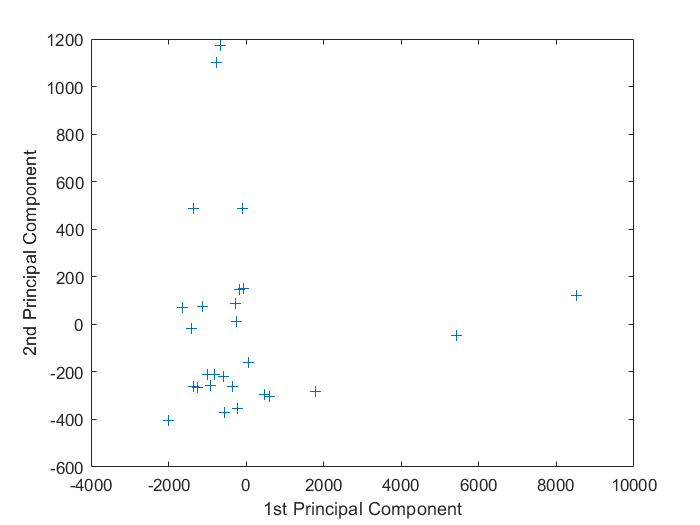

    figure
    plot(score(:,1),score(:,2),'+');
    xlabel('1st Principal Component')
    ylabel('2nd Principal Component')

    % name=gname%极端数据
    latent,explained%成分的差异、方差百分比解释

latent = 	1.0e+06 *

    4.8322
    0.1639
    0.0679
    0.0275
    0.0113
    0.0064
    0.0031
    0.0017
    0.0017
    0.0015


explained =    94.3608
    3.2006
    1.3251
    0.5370
    0.2213
    0.1250
    0.0603
    0.0334
    0.0325
    0.0288


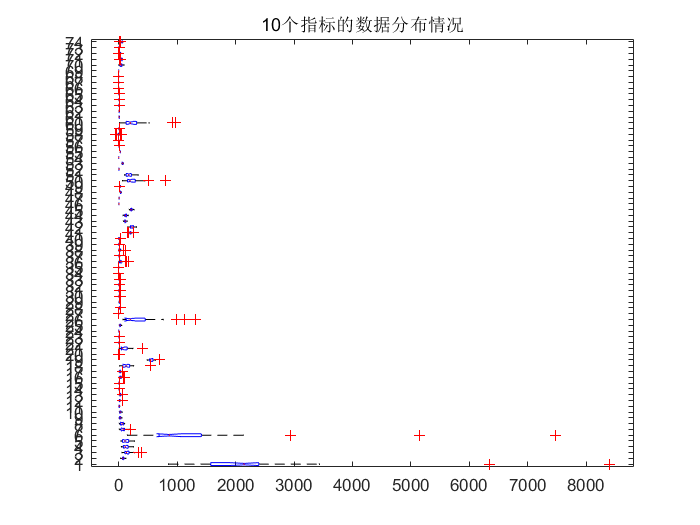

    figure
    pareto(explained)%制作每个主成分解释的变异百分比

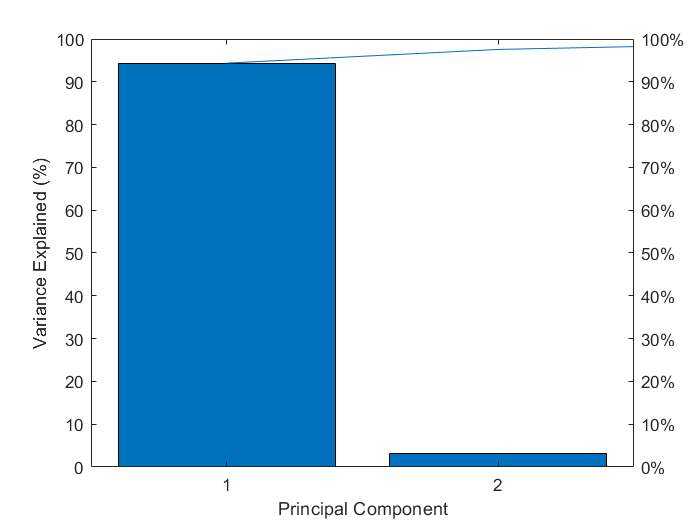

    xlabel('Principal Component')
    ylabel('Variance Explained (%)')

    [st2,index] = sort(tsquared,'descend');
    extreme = index(1)

extreme = 16

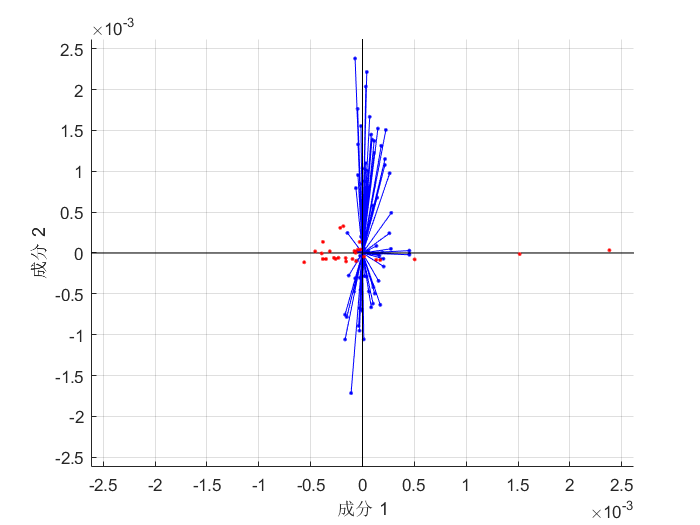

    figure
    biplot(coefforth(:,1:2),'Scores',score(:,1:2))

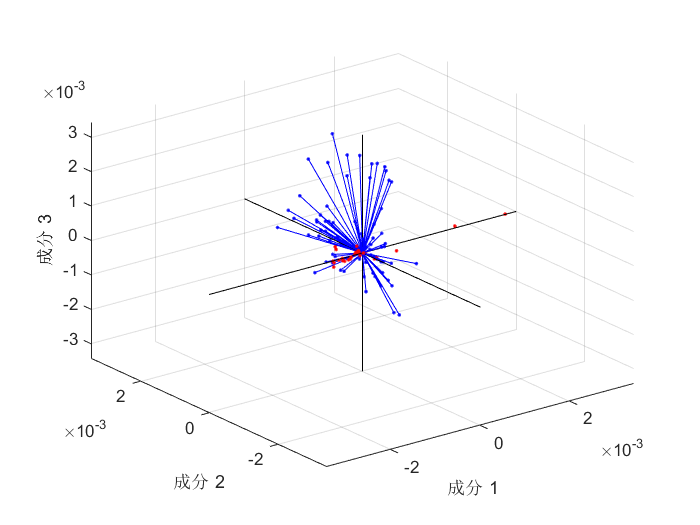

    figure
    biplot(coefforth(:,1:3),'Scores',score(:,1:3))

聚类分析；高斯混合模型

这里我用混合主成分（上面那个）

重新构造数据

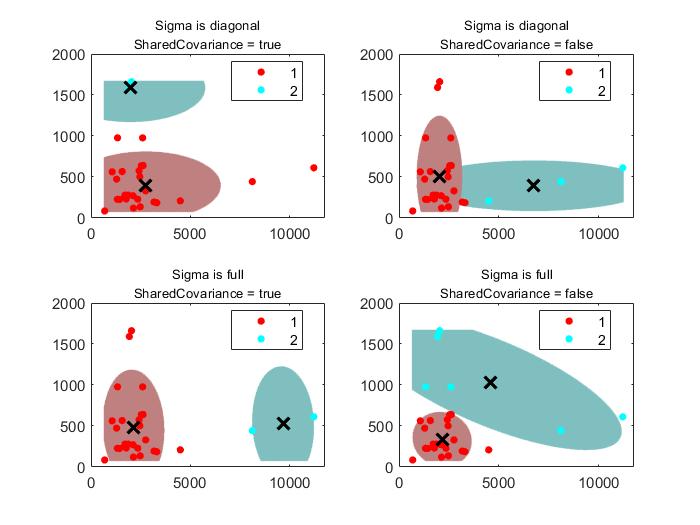

coeff=wcoeff(:,1:2)';
for ii=1:27
    for jj=1:2
        NewData(ii,jj)=sum(coeff(jj,:).*Data(ii,:),'all');
    end
end
X=NewData;
rng(3);
k = 2; % Number of GMM components
options = statset('MaxIter',1000);
Sigma = {'diagonal','full'}; % Options for covariance matrix type
nSigma = numel(Sigma);
SharedCovariance = {true,false}; % Indicator for identical or nonidentical covariance matrices
SCtext = {'true','false'};
nSC = numel(SharedCovariance);
d = 500; % Grid length
x1 = linspace(min(X(:,1))-2, max(X(:,1))+2, d);
x2 = linspace(min(X(:,2))-2, max(X(:,2))+2, d);
[x1grid,x2grid] = meshgrid(x1,x2);
X0 = [x1grid(:) x2grid(:)];
threshold = sqrt(chi2inv(0.99,2));
count = 1;
for i = 1:nSigma
 for j = 1:nSC
 gmfit = fitgmdist(X,k,'CovarianceType',Sigma{i}, ...
 'SharedCovariance',SharedCovariance{j},'Options',options); % Fitted GMM
 clusterX = cluster(gmfit,X); % Cluster index 
 mahalDist = mahal(gmfit,X0); % Distance from each grid point to each GMM component
 % Draw ellipsoids over each GMM component and show clustering result.
 subplot(2,2,count);
 h1 = gscatter(X(:,1),X(:,2),clusterX);
 hold on
 for m = 1:k
 idx = mahalDist(:,m)<=threshold;
 Color = h1(m).Color*0.75 - 0.5*(h1(m).Color - 1);
 h2 = plot(X0(idx,1),X0(idx,2),'.','Color',Color,'MarkerSize',1);
 uistack(h2,'bottom');
 end
 plot(gmfit.mu(:,1),gmfit.mu(:,2),'kx','LineWidth',2,'MarkerSize',10)
 title(sprintf('Sigma is %s\nSharedCovariance = %s',Sigma{i},SCtext{j}),'FontSize',8)
 legend(h1,{'1','2','3'})
 hold off
 count = count + 1;
 end
end

硬约束

X=NewData;
figure
scatter(X(:,1),X(:,2),10,'ko')
options = statset('Display','final'); 
gm = fitgmdist(X,2,'Options',options)

16 iterations, log-likelihood = -424.356

gm = 

在 2 个维中具有 2 个成分的高斯混合分布
成分 1:
混合比例: 0.220111
均值:   1.0e+03 *

    4.6047    1.0307

成分 2:
混合比例: 0.779889
均值:   1.0e+03 *

    2.1589    0.3377





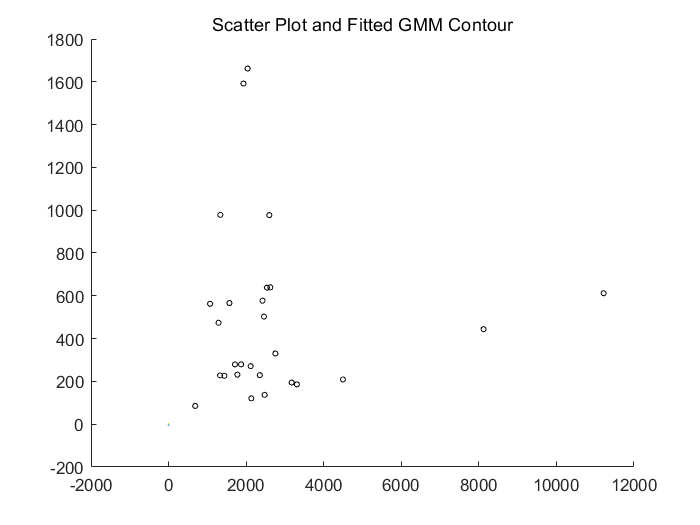

hold on
gmPDF = @(x,y) arrayfun(@(x0,y0) pdf(gm,[x0,y0]),x,y);
fcontour(gmPDF,[-8,6])
title('Scatter Plot and Fitted GMM Contour')
hold off

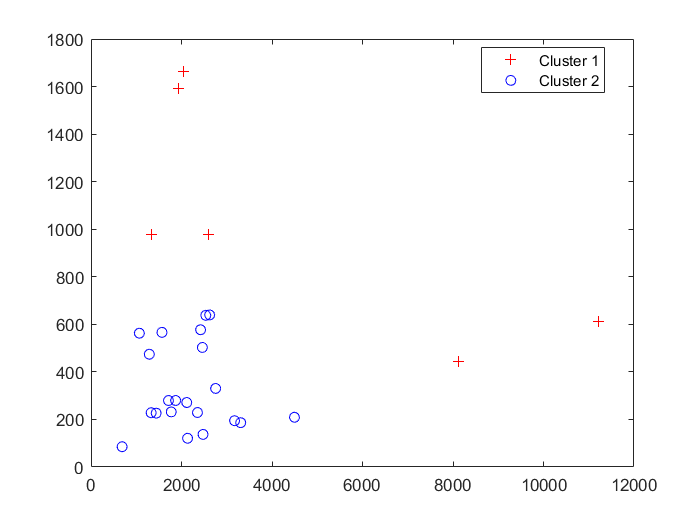

idx = cluster(gm,X);
cluster1 = (idx == 1); % |1| for cluster 1 membership
cluster2 = (idx == 2); % |2| for cluster 2 membership
figure
gscatter(X(:,1),X(:,2),idx,'rb','+o')
legend('Cluster 1','Cluster 2','Location','best')

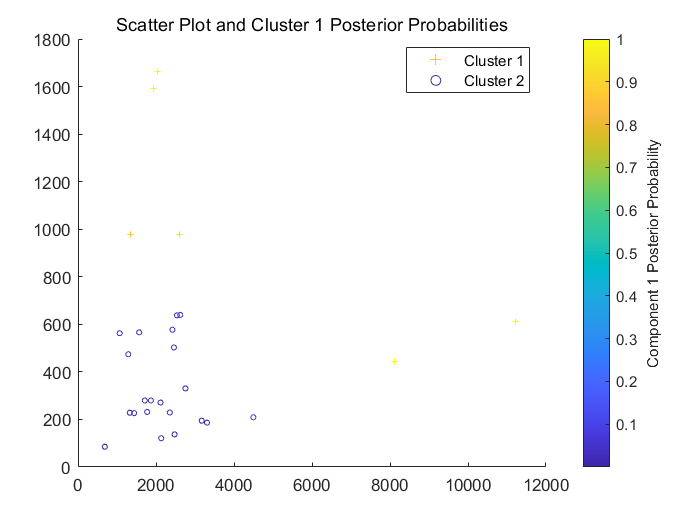

P = posterior(gm,X); 
figure
scatter(X(cluster1,1),X(cluster1,2),10,P(cluster1,1),'+')
hold on
scatter(X(cluster2,1),X(cluster2,2),10,P(cluster2,1),'o')
hold off
ylabel(colorbar,'Component 1 Posterior Probability')
legend('Cluster 1','Cluster 2','Location','best')
title('Scatter Plot and Cluster 1 Posterior Probabilities')

软约束

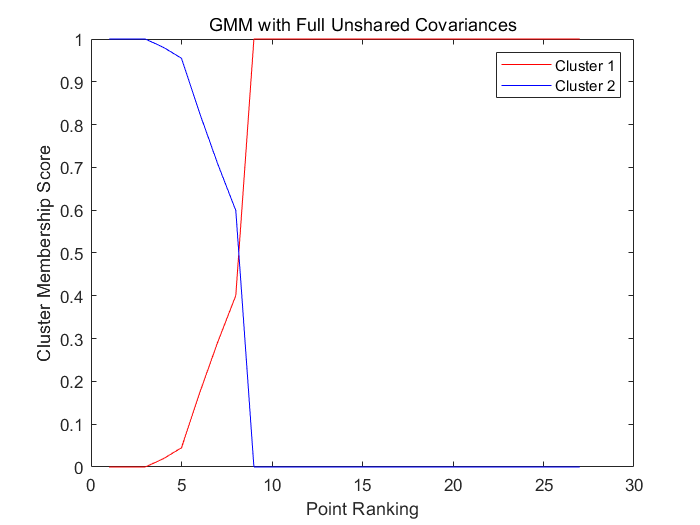

gm = fitgmdist(X,2);
threshold = [0.4 0.6];
P = posterior(gm,X);
n = size(X,1);
[~,order] = sort(P(:,1));
figure
plot(1:n,P(order,1),'r-',1:n,P(order,2),'b-')
legend({'Cluster 1', 'Cluster 2'})
ylabel('Cluster Membership Score')
xlabel('Point Ranking')
title('GMM with Full Unshared Covariances')

idx = cluster(gm,X);
idxBoth = find(P(:,1)>=threshold(1) & P(:,1)<=threshold(2)); 
numInBoth = numel(idxBoth)

numInBoth = 1

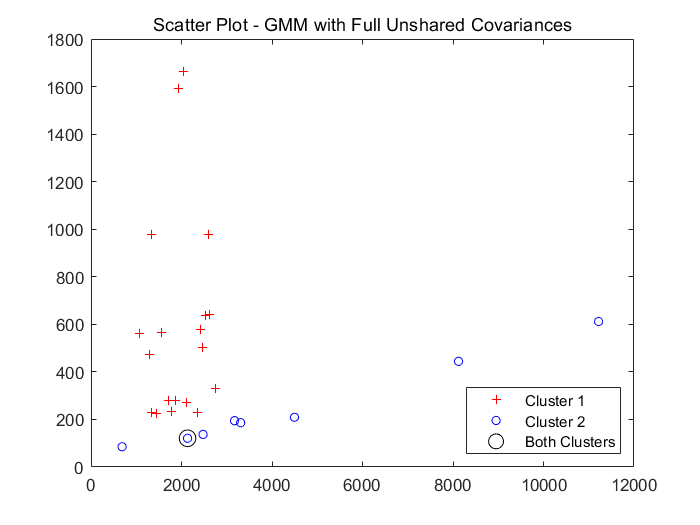

figure
gscatter(X(:,1),X(:,2),idx,'rb','+o',5)
hold on
plot(X(idxBoth,1),X(idxBoth,2),'ko','MarkerSize',10)
legend({'Cluster 1','Cluster 2','Both Clusters'},'Location','SouthEast')
title('Scatter Plot - GMM with Full Unshared Covariances')
hold off

gmSharedDiag = fitgmdist(X,2,'CovType','Diagonal', ...
 'SharedCovariance',true');
[idxSharedDiag,~,PSharedDiag] = cluster(gmSharedDiag,X);
idxBothSharedDiag = find(PSharedDiag(:,1)>=threshold(1) & ...
 PSharedDiag(:,1)<=threshold(2)); 
numInBoth = numel(idxBothSharedDiag)

numInBoth = 0

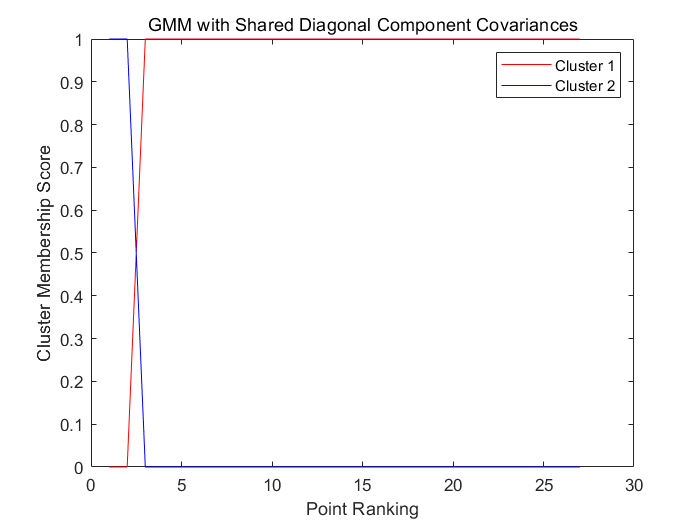

[~,orderSharedDiag] = sort(PSharedDiag(:,1));
figure
plot(1:n,PSharedDiag(orderSharedDiag,1),'r-',...
 1:n,PSharedDiag(orderSharedDiag,2),'b-')
legend({'Cluster 1' 'Cluster 2'},'Location','NorthEast')
ylabel('Cluster Membership Score')
xlabel('Point Ranking')
title('GMM with Shared Diagonal Component Covariances')

figure
gscatter(X(:,1),X(:,2),idxSharedDiag,'rb','+o',5)
hold on
plot(X(idxBothSharedDiag,1),X(idxBothSharedDiag,2),'ko','MarkerSize',10)
legend({'Cluster 1','Cluster 2','Both Clusters'},'Location','SouthEast')

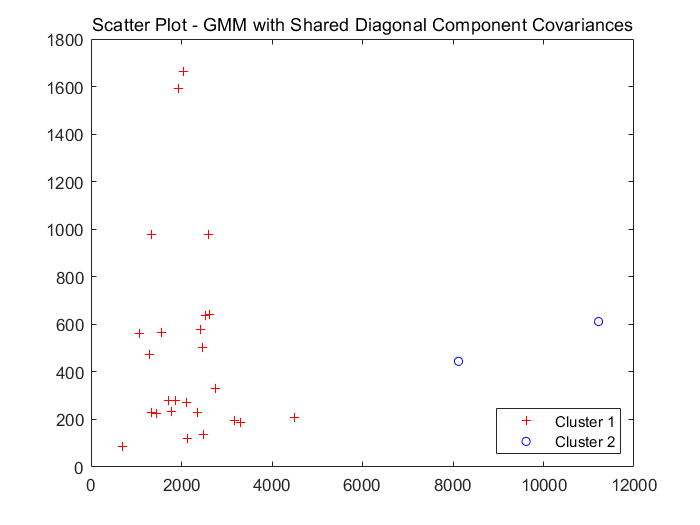

title('Scatter Plot - GMM with Shared Diagonal Component Covariances')
hold off

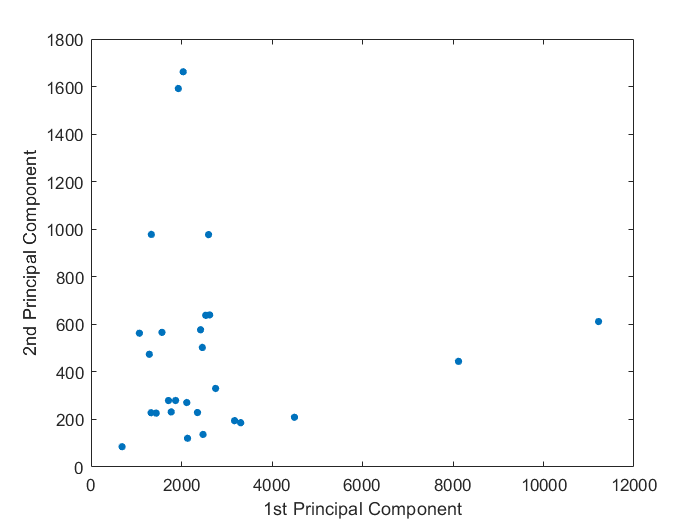

[n,p] = size(X);
rng(1) % For reproducibility
figure
plot(X(:,1),X(:,2),'.','MarkerSize',15)
% title('Fisher''s Iris Data Set')
xlabel('1st Principal Component')
ylabel('2nd Principal Component')

k = 1:5;
nK = numel(k);
Sigma = {'diagonal','full'};
nSigma = numel(Sigma);
SharedCovariance = {true,false};
SCtext = {'true','false'};
nSC = numel(SharedCovariance);
RegularizationValue = 0.01;
options = statset('MaxIter',10000);
% Preallocation
gm = cell(nK,nSigma,nSC); 
aic = zeros(nK,nSigma,nSC);
bic = zeros(nK,nSigma,nSC);
converged = false(nK,nSigma,nSC);
% Fit all models
for m = 1:nSC
 for j = 1:nSigma
 for i = 1:nK
 gm{i,j,m} = fitgmdist(X,k(i),...
 'CovarianceType',Sigma{j},...
 'SharedCovariance',SharedCovariance{m},...
 'RegularizationValue',RegularizationValue,...
 'Options',options);
 aic(i,j,m) = gm{i,j,m}.AIC;
 bic(i,j,m) = gm{i,j,m}.BIC;
 converged(i,j,m) = gm{i,j,m}.Converged;
 end
 end
end
allConverge = (sum(converged(:)) == nK*nSigma*nSC)

allConverge = logical
   1


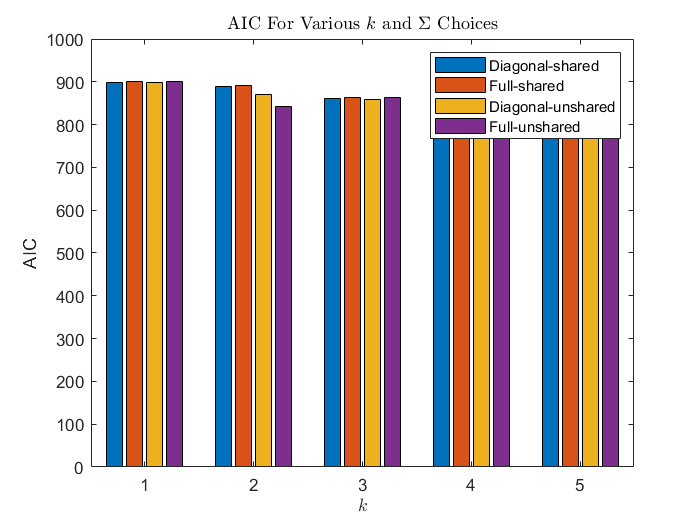

figure
bar(reshape(aic,nK,nSigma*nSC))
title('AIC For Various $k$ and $\Sigma$ Choices','Interpreter','latex')
xlabel('$k$','Interpreter','Latex')
ylabel('AIC')
legend({'Diagonal-shared','Full-shared','Diagonal-unshared',...
 'Full-unshared'})

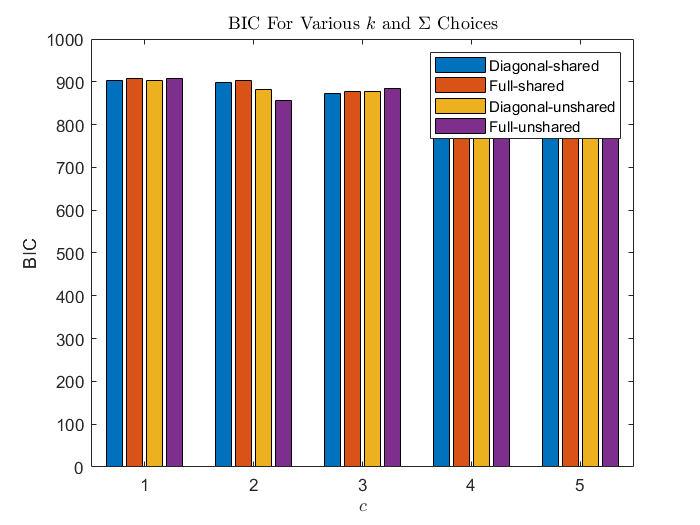

figure
bar(reshape(bic,nK,nSigma*nSC))
title('BIC For Various $k$ and $\Sigma$ Choices','Interpreter','latex')
xlabel('$c$','Interpreter','Latex')
ylabel('BIC') 
legend({'Diagonal-shared','Full-shared','Diagonal-unshared',...
 'Full-unshared'})

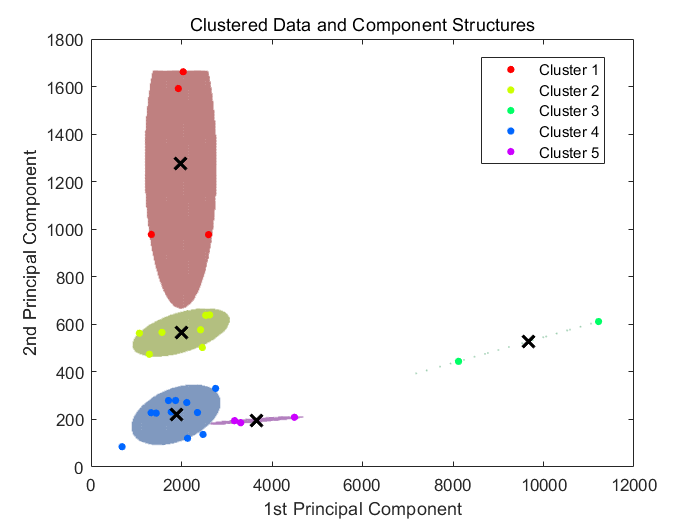

gmBest = gm{5,2,2};
clusterX = cluster(gmBest,X);
kGMM = gmBest.NumComponents;
d = 500;
x1 = linspace(min(X(:,1)) - 2,max(X(:,1)) + 2,d);
x2 = linspace(min(X(:,2)) - 2,max(X(:,2)) + 2,d);
[x1grid,x2grid] = meshgrid(x1,x2);
X0 = [x1grid(:) x2grid(:)];
mahalDist = mahal(gmBest,X0);
threshold = sqrt(chi2inv(0.99,2));
figure
h1 = gscatter(X(:,1),X(:,2),clusterX);
hold on
for j = 1:kGMM
 idx = mahalDist(:,j)<=threshold;
 Color = h1(j).Color*0.75 + -0.5*(h1(j).Color - 1);
 h2 = plot(X0(idx,1),X0(idx,2),'.','Color',Color,'MarkerSize',1);
 uistack(h2,'bottom')
end
plot(gmBest.mu(:,1),gmBest.mu(:,2),'kx','LineWidth',2,'MarkerSize',10)
title('Clustered Data and Component Structures')
xlabel('1st Principal Component')
ylabel('2nd Principal Component')
legend(h1,'Cluster 1','Cluster 2','Cluster 3','Cluster 4','Cluster 5','Location','best')
hold off

分析两组指标之间关系$AX=BY
$


$$\left\lbrace \begin{array}{ll}
a_{11} x_1 +a_{12} x_2 +\ldotp \ldotp \ldotp +a_{1n} x_n =b_{11} y_1 +b_{12} y_2 +\ldotp \ldotp \ldotp +b_{1n} y_m  & \\
a_{21} x_1 +a_{22} x_2 +\ldotp \ldotp \ldotp +a_{2n} x_n =b_{21} y_1 +b_{22} y_2 +\ldotp \ldotp \ldotp +b_{2n} y_m  & 
\end{array}\right.$$


 [A,B,r,U,V,stats]=canoncorr(Dataliangjiuhong,Datahongjiu)

A =     0.0007    0.0357    0.0059    0.0207    0.0164    0.0602    0.0337   -0.0047   -0.0132    0.0180   -0.0355   -0.0380   -0.0315   -0.0625   -0.0110
   -0.1066   -0.1587   -0.0276   -0.0586   -0.1019   -0.2496   -0.0750    0.0148    0.1018   -0.1230    0.1284    0.2127    0.1571    0.1722    0.0268
   -0.0404   -0.0680   -0.0175   -0.0305   -0.0325   -0.1248   -0.0883   -0.0047    0.0573   -0.0381    0.0476    0.1144    0.0540    0.0996    0.0177
   -0.0117   -0.0755   -0.0092   -0.0460   -0.0500   -0.1275   -0.0548    0.0299    0.0256   -0.0445    0.0964    0.0887    0.0857    0.1447    0.0232
    0.0577   -0.0043    0.0019   -0.0131    0.0161    0.0056   -0.0290   -0.0029   -0.0293    0.0117    0.0143   -0.0194    0.0017    0.0028   -0.0012
   -0.0001   -0.0337   -0.0055   -0.0185   -0.0160   -0.0575   -0.0316    0.0050    0.0113   -0.0180    0.0344    0.0361    0.0309    0.0601    0.0106
   -0.0047   -0.0337   -0.0079   -0.0006   -0.0167   -0.0611   -0.0347    0.0114    0.0016

B = 	1.0e+04 *

    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.0000   -0.0000         0   -0.0000    0.0001    0.0000    0.0000   -0.0000   -0.0000    0.0001   -0.0001    0.0000    0.0000    0.0000    0.0000
    0.0001   -0.0001         0    0.0000    0.0000   -0.0000   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0001   -0.0001   -0.0002    0.0001
   -0.0000    0.0000         0    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001   -0.0000
   -0.9279   -0.3194         0    0.1334    0.2546   -0.9313   -1.0284   -0.4035   -0.1995   -0.6260    1.0073    0.6961   -0.0139   -0.3315   -0.2183
    0.9279    0.3193         0   -0.1334   -0.2546    0.9314    1.0285    0.4035    0.1995    0.6261   -1.0073   -0.6961    0.0138    0.3315    0.2183
    0.9279    0.3195         0   -0.1334   -0.2547    0.9314    1.0284    0.40

r =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


U =     1.1366   -1.2000   -3.0864   -0.3244    0.1776   -1.1332    0.5137   -0.8878    0.3573    0.7980    1.5854   -1.5993    0.3244    0.0378   -1.1552
   -0.4800    0.5151   -1.1028   -0.7924   -2.0311    1.6161    1.2521    1.5658    0.0907    0.2454    1.2537    1.6108    1.1904    1.6814    0.1195
   -2.1312    0.2081   -0.5863   -0.9803    1.2849   -0.8585    0.6620   -1.1563   -1.6203   -0.2225   -1.5523    0.1898    1.8062    0.7816   -0.0546
   -0.1595    0.1313    0.3494   -0.4830    0.9812    0.2716   -0.8879   -0.2454    0.2932   -0.0451    0.2890    0.8094   -0.9363   -0.7378    0.6845
   -1.0233    0.9723   -0.0708    0.1882   -0.5898   -0.7212   -0.6227    0.3244    0.8357   -0.7751    0.3773   -1.1348   -0.8337   -0.1922   -0.2657
    0.4230    1.0135    0.6385    0.9592   -0.8778   -0.8453   -1.8333    0.4578    0.4776    0.1813    0.5125    0.5682    1.7387   -0.3364   -0.2335
    0.4919    1.3525    0.7524    0.0544    1.0050   -0.2101    0.7224   -0.9932    0.0636

V =     1.1366   -1.2000   -3.0864   -0.3244    0.1776   -1.1332    0.5137   -0.8878    0.3573    0.7980    1.5854   -1.5993    0.3244    0.0378   -1.1552
   -0.4800    0.5151   -1.1028   -0.7924   -2.0311    1.6161    1.2521    1.5658    0.0907    0.2454    1.2537    1.6108    1.1904    1.6814    0.1195
   -2.1312    0.2081   -0.5863   -0.9803    1.2849   -0.8585    0.6620   -1.1563   -1.6203   -0.2225   -1.5523    0.1898    1.8062    0.7816   -0.0546
   -0.1595    0.1313    0.3494   -0.4830    0.9812    0.2716   -0.8879   -0.2454    0.2932   -0.0451    0.2890    0.8094   -0.9363   -0.7378    0.6845
   -1.0233    0.9723   -0.0708    0.1882   -0.5898   -0.7212   -0.6227    0.3244    0.8357   -0.7751    0.3773   -1.1348   -0.8337   -0.1922   -0.2657
    0.4230    1.0135    0.6385    0.9592   -0.8778   -0.8453   -1.8333    0.4578    0.4776    0.1813    0.5125    0.5682    1.7387   -0.3364   -0.2335
    0.4919    1.3525    0.7524    0.0544    1.0050   -0.2101    0.7224   -0.9932    0.0636

stats = 包含以下字段的 struct :
     Wilks: [0 0 0 0 0 0 0 0 0 0 0 7.2926e-63 3.2843e-47 1.4791e-31 6.6613e-16]
       df1: [390 350 312 276 242 210 180 152 126 102 80 60 42 26 12]
       df2: [-128.8559 -112.7387 -97.6544 -83.6076 -70.6036 -58.6490 -47.7511 -37.9190 -29.1631 -21.4956 -14.9304 -9.4825 -5.1676 -2 0]
         F: [-Inf -Inf -Inf -Inf -Inf -Inf -Inf -Inf -Inf -Inf -Inf -1.3095e+15 -5.7497e+14 -2.0001e+14 0]
        pF: [NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN]
     chisq: [Inf Inf Inf Inf Inf Inf Inf Inf Inf Inf Inf 715.3800 535.1617 354.9435 174.7252]
    pChisq: [0 0 0 0 0 0 0 0 0 0 0 6.2946e-113 9.7203e-87 1.8384e-59 5.1479e-31]
       dfe: [390 350 312 276 242 210 180 152 126 102 80 60 42 26 12]
         p: [0 0 0 0 0 0 0 0 0 0 0 6.2946e-113 9.7203e-87 1.8384e-59 5.1479e-31]


考虑从理化性质，附件3降维，此处还是用PCA?，效果似乎不是很好

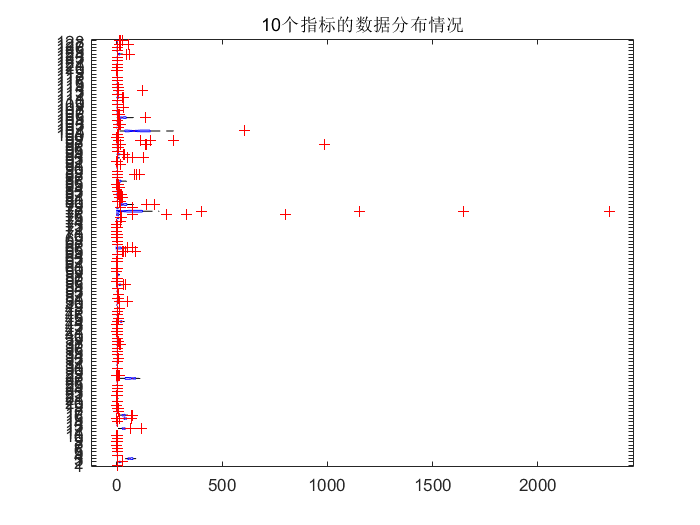

Data=[hongfangxiangjiu',hongfangxiangputao'];
    boxplot(Data,'Notch',"on",'Orientation','horizontal')
    title('10个指标的数据分布情况')

    C=corr(Data,Data)%检查成对相关性

C =     1.0000    0.2625    0.3731    0.0241    0.1562   -0.3038    0.0515   -0.1353    0.0881   -0.0294    0.5000    0.1105    0.0064   -0.0337    0.5166   -0.0646   -0.0062   -0.0261    0.0910   -0.0236    0.2336    0.5721    0.3193    0.3445   -0.0401   -0.0526   -0.0385    0.2205    0.0020   -0.0758   -0.0808   -0.1706    0.2009   -0.1836   -0.0924   -0.1253   -0.1292    0.1619    0.2201   -0.0222    0.0180    0.0061    0.4152   -0.4194   -0.0081   -0.0134    0.0429   -0.3764    0.1300   -0.1347
    0.2625    1.0000    0.3371   -0.0529    0.7954   -0.0471    0.7410   -0.2060   -0.0013   -0.1245    0.5247    0.8091    0.6022    0.3806    0.4187    0.0507    0.5261    0.5269    0.2344    0.5708    0.1045    0.1524    0.2729    0.0663    0.5922    0.0960    0.4148    0.0828    0.1328   -0.1960    0.2254    0.3554    0.1941    0.1167    0.0285    0.0756    0.1733    0.3004    0.1335   -0.2127    0.1563   -0.2708    0.6443   -0.0312    0.2930   -0.1164   -0.1848    0.4423    0.0391   -0

    w=1./var(Data);
    [wcoeff,score,latent,tsquared,explained]=pca(Data,'Centered',true,'Options',options)%主成分分析开始

wcoeff =    -0.0003    0.0008    0.0007   -0.0026    0.0113   -0.0250   -0.0016    0.0090   -0.0038   -0.0109    0.0005   -0.0016    0.0255    0.0207    0.0201    0.0547    0.0087    0.0996   -0.0972   -0.0292   -0.0077   -0.0528   -0.0834    0.1759    0.0019    0.0798
   -0.0012   -0.0041    0.0124    0.0590    0.1282   -0.0428    0.0620    0.0139    0.0977    0.0637    0.0075    0.1172   -0.0906    0.0496   -0.0445    0.1780   -0.0221    0.1409    0.0400    0.0563   -0.0987   -0.1325    0.3431   -0.0690    0.1558    0.0964
    0.0027    0.0167   -0.0279   -0.0248    0.1856   -0.2532    0.3920    0.4469   -0.0506   -0.1193    0.0820    0.0362    0.0202   -0.0090   -0.1271    0.0584    0.4328   -0.2533   -0.0284   -0.0141    0.1053   -0.0846    0.1739    0.2247    0.0241    0.0298
    0.0010    0.0041   -0.0002   -0.0006    0.0053   -0.0023   -0.0048    0.0006    0.0037    0.0012   -0.0016    0.0004    0.0066   -0.0012   -0.0057    0.0034   -0.0058    0.0027   -0.0152   -0.0096   -0.01

score = 	1.0e+03 *

   -0.2454    0.0364   -0.0137   -0.0700   -0.0434    0.0072    0.0125   -0.0134    0.0081    0.0077   -0.0054    0.0025   -0.0107   -0.0069    0.0020   -0.0078    0.0005    0.0005    0.0000    0.0030    0.0048    0.0001    0.0005    0.0048   -0.0009    0.0007
   -0.2495    0.0286   -0.0470   -0.0626   -0.0490    0.0155    0.0123   -0.0228   -0.0017    0.0070   -0.0143    0.0020    0.0066   -0.0035    0.0010    0.0031   -0.0048    0.0029   -0.0003   -0.0001   -0.0032    0.0049   -0.0002   -0.0045   -0.0003   -0.0004
   -0.2547    0.0139   -0.0714    0.0218   -0.0286    0.0076    0.0581    0.0055   -0.0118   -0.0155   -0.0042    0.0069    0.0178    0.0076   -0.0031    0.0023    0.0049   -0.0066    0.0003   -0.0020   -0.0000   -0.0033    0.0006    0.0008    0.0004    0.0004
   -0.1924   -0.0168   -0.0492    0.0160   -0.0187    0.0149   -0.0262   -0.0053   -0.0211    0.0152    0.0072   -0.0131   -0.0037   -0.0038    0.0026   -0.0014    0.0130    0.0032    0.0020   -0.0

latent = 	1.0e+05 *

    3.8570
    0.1159
    0.0420
    0.0127
    0.0066
    0.0052
    0.0040
    0.0034
    0.0027
    0.0021


tsquared =    25.0370
   25.0370
   25.0370
   25.0370
   25.0370
   25.0370
   25.0370
   25.0370
   25.0370
   25.0370


explained =    95.0544
    2.8564
    1.0350
    0.3132
    0.1627
    0.1293
    0.0992
    0.0831
    0.0677
    0.0511


    c3=wcoeff(:,1:end)%成分系数

c3 =    -0.0003    0.0008    0.0007   -0.0026    0.0113   -0.0250   -0.0016    0.0090   -0.0038   -0.0109    0.0005   -0.0016    0.0255    0.0207    0.0201    0.0547    0.0087    0.0996   -0.0972   -0.0292   -0.0077   -0.0528   -0.0834    0.1759    0.0019    0.0798
   -0.0012   -0.0041    0.0124    0.0590    0.1282   -0.0428    0.0620    0.0139    0.0977    0.0637    0.0075    0.1172   -0.0906    0.0496   -0.0445    0.1780   -0.0221    0.1409    0.0400    0.0563   -0.0987   -0.1325    0.3431   -0.0690    0.1558    0.0964
    0.0027    0.0167   -0.0279   -0.0248    0.1856   -0.2532    0.3920    0.4469   -0.0506   -0.1193    0.0820    0.0362    0.0202   -0.0090   -0.1271    0.0584    0.4328   -0.2533   -0.0284   -0.0141    0.1053   -0.0846    0.1739    0.2247    0.0241    0.0298
    0.0010    0.0041   -0.0002   -0.0006    0.0053   -0.0023   -0.0048    0.0006    0.0037    0.0012   -0.0016    0.0004    0.0066   -0.0012   -0.0057    0.0034   -0.0058    0.0027   -0.0152   -0.0096   -0.0125  

    coefforth=diag(std(Data))\wcoeff%变换矩阵

coefforth =    -0.0003    0.0008    0.0007   -0.0024    0.0105   -0.0232   -0.0015    0.0084   -0.0035   -0.0101    0.0005   -0.0015    0.0237    0.0192    0.0187    0.0508    0.0081    0.0926   -0.0904   -0.0271   -0.0072   -0.0491   -0.0776    0.1636    0.0017    0.0742
   -0.0002   -0.0008    0.0024    0.0113    0.0245   -0.0082    0.0118    0.0027    0.0187    0.0122    0.0014    0.0224   -0.0173    0.0095   -0.0085    0.0340   -0.0042    0.0269    0.0076    0.0108   -0.0189   -0.0253    0.0655   -0.0132    0.0298    0.0184
    0.0002    0.0012   -0.0019   -0.0017    0.0129   -0.0176    0.0273    0.0311   -0.0035   -0.0083    0.0057    0.0025    0.0014   -0.0006   -0.0088    0.0041    0.0301   -0.0176   -0.0020   -0.0010    0.0073   -0.0059    0.0121    0.0156    0.0017    0.0021
    0.0013    0.0051   -0.0003   -0.0008    0.0065   -0.0029   -0.0059    0.0007    0.0045    0.0015   -0.0019    0.0005    0.0081   -0.0015   -0.0070    0.0042   -0.0072    0.0033   -0.0186   -0.0117   -0

    I=coefforth'*coefforth%检查系数

I =     0.0001    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0001    0.0000   -0.0001   -0.0001    0.0001   -0.0001    0.0003   -0.0001   -0.0002    0.0000   -0.0004   -0.0002   -0.0001   -0.0002    0.0003   -0.0004   -0.0002    0.0001   -0.0004
    0.0001    0.0008   -0.0002   -0.0003   -0.0002   -0.0001    0.0008    0.0007    0.0002   -0.0000    0.0006   -0.0002    0.0007    0.0005   -0.0005   -0.0004    0.0005   -0.0004   -0.0008   -0.0008   -0.0018   -0.0006   -0.0004    0.0038    0.0010    0.0032
   -0.0000   -0.0002    0.0019    0.0009    0.0009    0.0004   -0.0018    0.0003    0.0007    0.0028   -0.0007   -0.0008   -0.0021    0.0014    0.0018   -0.0013   -0.0013    0.0019   -0.0003    0.0020   -0.0002    0.0045   -0.0037   -0.0053    0.0002    0.0050
   -0.0000   -0.0003    0.0009    0.0072    0.0006   -0.0001    0.0014   -0.0014    0.0010   -0.0005    0.0002    0.0019   -0.0044   -0.0002   -0.0002    0.0015    0.0002    0.0101    0.0068    0.0015   -0.0019   

    cscores=zscore(Data)*coefforth%成分分数

cscores =    -0.0165    0.0380   -0.1191   -0.4917   -0.5804    0.2779    0.3237   -0.1704   -0.1055    0.0072   -0.3001   -0.1032    0.1574   -0.6529    0.0854   -0.6822    0.9115   -1.0696    0.2540    0.6033    1.3523    0.3794   -0.1784    4.1785   -0.7217    2.6252
   -0.0153    0.0058   -0.1542   -0.4698   -0.5440    0.2188    0.2310   -0.2919   -0.1977    0.0099   -0.3042   -0.3452    0.1967   -0.5940    0.0251   -0.0434    0.0568   -0.7140   -0.4593    0.0665   -0.4685    1.3469   -0.9502   -2.1334    0.4948   -1.0578
   -0.0119    0.0784   -0.3742    0.0389   -0.9247   -0.0122    2.0143    0.4493   -0.7117   -1.0856   -0.2066    0.3544    1.7924    0.0621   -1.1049   -0.1696    2.5030   -2.8259    1.0949   -0.8819    0.6596   -4.0948    1.7023    2.8736    0.2226    1.1843
   -0.0217   -0.0476   -0.0014    0.0606   -0.3623    0.1897   -0.2470   -0.2670   -0.3018    0.0289   -0.0088   -0.5399   -0.3254   -0.1751    0.0211    0.4477    1.3988    0.7829    0.7412   -0.1500    1.4

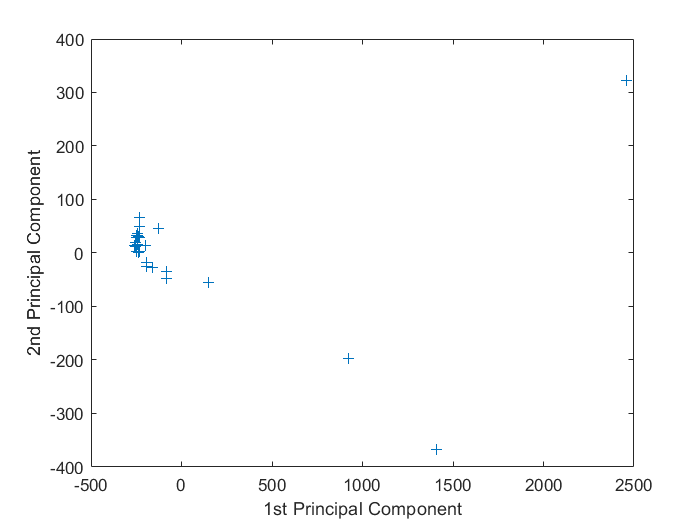

    figure
    plot(score(:,1),score(:,2),'+');
    xlabel('1st Principal Component')
    ylabel('2nd Principal Component')

    % name=gname%极端数据
    latent,explained%成分的差异、方差百分比解释

latent = 	1.0e+05 *

    3.8570
    0.1159
    0.0420
    0.0127
    0.0066
    0.0052
    0.0040
    0.0034
    0.0027
    0.0021


explained =    95.0544
    2.8564
    1.0350
    0.3132
    0.1627
    0.1293
    0.0992
    0.0831
    0.0677
    0.0511


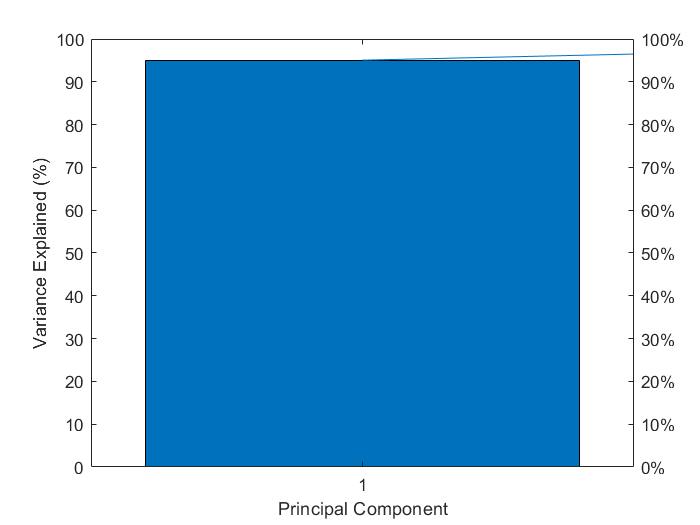

    figure
    pareto(explained)%制作每个主成分解释的变异百分比
    xlabel('Principal Component')
    ylabel('Variance Explained (%)')

    [st2,index] = sort(tsquared,'descend');
    extreme = index(1)

extreme = 18

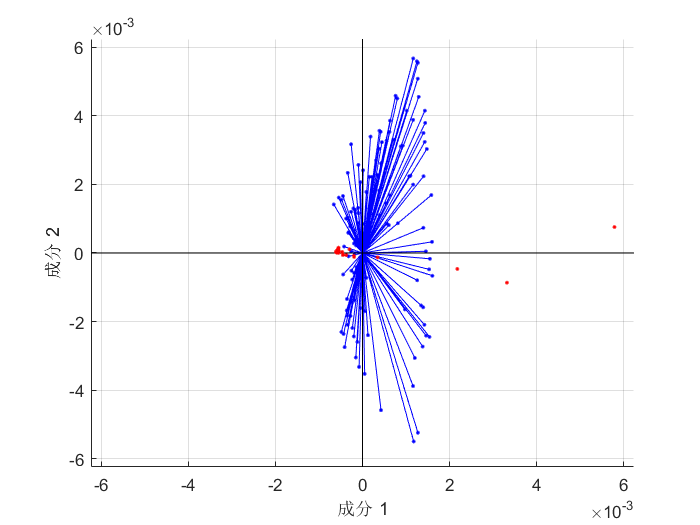

    figure
    biplot(coefforth(:,1:2),'Scores',score(:,1:2))

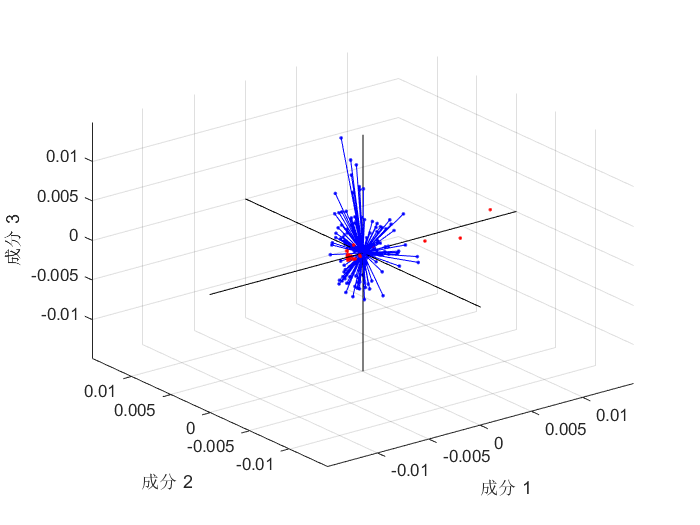

    figure
    biplot(coefforth(:,1:3),'Scores',score(:,1:3))

    
    
[Y0,loss0]=tsne(Data)

Y0 = 	1.0e+03 *

    0.4512    0.5622
    0.2958    0.7182
   -0.8044   -0.0744
   -0.1658   -0.0259
    0.5877   -1.2249
    0.7171    0.2415
   -0.5755    0.0382
    0.0811    0.1222
   -0.4989    0.3888
   -0.3875   -0.1130


loss0 = 0.3310

[Y1,loss1]=tsne([Dataliangjiuhong,Datahongjiu])

Y1 =  -667.7168  182.3269
 -161.8161  715.2000
 -547.9940 -901.0524
  -98.6343  168.0269
  374.4274  470.8479
 -547.2281 -486.6400
 -373.7081  464.3835
 -668.5294  355.7967
 -144.4876  437.3100
  427.0233 -322.8821


loss1 = 0.2814